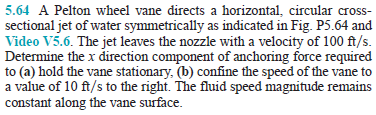

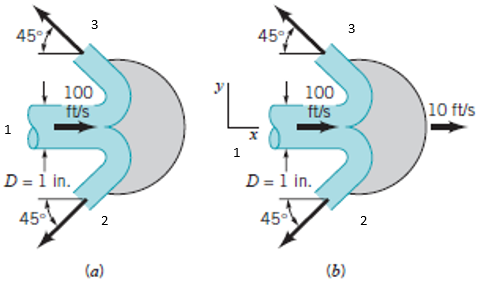

# inflow properties

% ----------------
u = symunit;
rho = 1.94*u.slug/u.ft^3;
D1 = 1*u.in;
A1 = sympi*D1^2/4;
% ----------------
V1 = 100*u.ft/u.s;
Vcv = 10*u.ft/u.s;
% ----------------
W1_a = V1;
W1x_a = W1_a;
W1y_a = 0;
% ----------------
W1_b = abs(V1-Vcv);
W1x_b = W1_b;
W1y_b = 0;
% ----------------
mdot1_a = rewrite(rho*A1*W1_a, 'US');
mdot1_b = rewrite(rho*A1*W1_b, 'US');
% ----------------

# outflow properties

% ----------------
theta = 45*u.deg;
% ----------------
W2_a = W1_a;
W2x_a = W2_a*cos(theta);
W2y_a = W2_a*sin(theta);
W3_a = W1_a;
W3x_a = W3_a*cos(theta);
W3y_a = W3_a*sin(theta);
% ----------------
W2_b = W1_b;
W2x_b = W2_b*cos(theta);
W2y_b = W2_b*sin(theta);
W3_b = W1_b;
W3x_b = W3_b*cos(theta);
W3y_b = W3_b*sin(theta);
% ----------------

# conservation of mass

% ----------------
syms mdot2_a mdot3_a;
eqn_a = sym.zeros(3,1);
eqn_a(1) = mdot1_a == mdot2_a+mdot3_a;
% ----------------
syms mdot2_b mdot3_b;
eqn_b = sym.zeros(3,1);
eqn_b(1) = mdot1_b == mdot2_b+mdot3_b;
% ----------------

# conservation of momentum (x-direction)

% ----------------
syms Fx_a;
eqn_a(2) = Fx_a == -mdot1_a*(W1x_a)+mdot2_a*(-W2x_a)+mdot3_a*(-W3x_a);
% ----------------
syms Fx_b;
eqn_b(2) = Fx_b == -mdot1_b*(W1x_b)+mdot2_b*(-W2x_b)+mdot3_b*(-W3x_b);
% ----------------

# conservation of momentum (y-direction)

% ----------------
eqn_a(3) = 0 == -mdot1_a*(W1y_a)+mdot2_a*(-W2y_a)+mdot3_a*(W3y_a);
% ----------------
eqn_b(3) = 0 == -mdot1_b*(W1y_b)+mdot2_b*(-W2y_b)+mdot3_b*(W3y_b);
% ----------------

# anchoring forces

% ----------------
eqn_a = simplify(eqn_a);
[Fx_a mdot2_a mdot3_a] = solve(eqn_a, [Fx_a mdot2_a mdot3_a]); %#ok
Fx_a = rewrite(simplify(Fx_a), u.lbf);
Fx_a_vpa = vpa(Fx_a, 5) %#ok

$$Fx\_a\_vpa = -180.63\,\mathrm{lbf}$$

clear Fx_a_vpa;
% ----------------
eqn_b = simplify(eqn_b);
[Fx_b mdot2_b mdot3_b] = solve(eqn_b, [Fx_b mdot2_b mdot3_b]); %#ok
Fx_b = rewrite(simplify(Fx_b), u.lbf);
Fx_b_vpa = vpa(Fx_b, 5) %#ok

$$Fx\_b\_vpa = -146.31\,\mathrm{lbf}$$

clear Fx_b_vpa;
% ----------------